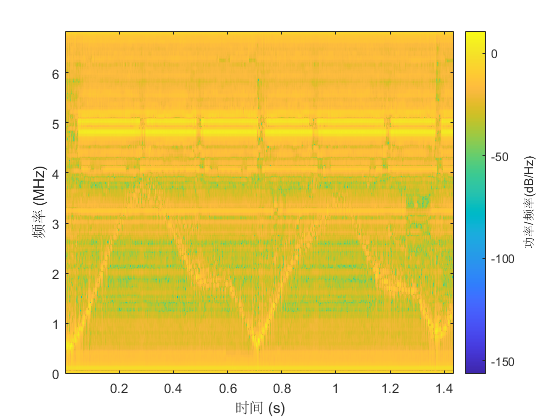

% FUNC:Batch folder processing of radar data for each aquactic human activity is performed to generate range-time maps, 
% Doppler-time maps, cadence velocity diagrams and SVM feature extraction datasets.

clc;clear;close all;
data_path = 'H:\RadarProcessing\DataFile\PaperData\';
act = 'freestyle';
real_data_path = strcat(data_path,act,'\');
files = dir(real_data_path);

f0 = 60e9;  
% f0 = 60.25e9;  
c = physconst('lightspeed'); 
lambda = c / f0; 
D = lambda / 2; 
num_rx = 4; 
% num_tx = 3; 
num_tx = 2;
chirp_num = 128;



% idel_time = 7e-6; 
% ramp_time = 57e-6; 
% TC = (idel_time + ramp_time) * num_tx; 
% TF = TC * chirp_num;
% frame_length = 100; 
% overlap = 0.25;
% slope = 64.985e12;
% adc_sample = 256; 
% fs_sample = 4000e3; 

idel_time = 30e-6; 
ramp_time = 80e-6; 
TC = (idel_time + ramp_time) * num_tx; 
TF = TC * chirp_num;
% frame_length = 60; 
frame_length = 60; 
% overlap = 0.25;
overlap = 0.25;
% slope = 46.395e12;
slope = 49.97e12;
adc_sample = 256; 
fs_sample=6500e3;


range_res = 3e8 / (2 * 1 / fs_sample * adc_sample * slope); 
range_fft_sample = 256; 
doppler_fft_sample = 128; 
% range_axis = [-range_fft_sample / 2 : range_fft_sample / 2 - 1] * range_res / (range_fft_sample / adc_sample); 
range_axis = [1 : range_fft_sample] * range_res / (range_fft_sample / adc_sample); 
velocity_res = 3e8 / (2 * f0 * TF); 
velocity_axis = [-doppler_fft_sample / 2 : doppler_fft_sample / 2 - 1] * velocity_res / (doppler_fft_sample / chirp_num);
frame_axis = (1:frame_length/overlap)*100/1000*overlap;

% for idx = 3:length(files)
%     file_path = strcat(real_data_path,files(idx).name,'\');
%     son_file = dir(file_path);
%     bin_path = strcat(file_path,son_file(4).name);
%     [ADC_DATA] = readDCA1000(bin_path);
%     [ADC_DATA] = readDCA1000('../6.13数据/H1_zou2_Raw_0.bin');
%     [ADC_DATA] = readDCA1000('H2_zou2_Raw_0.bin');
% [ADC_DATA] = readDCA1000('Z1_zou3_Raw_0.bin');


% [ADC_DATA] = readDCA1000('7.26/Z_41_Raw_0.bin');
[ADC_DATA] = readDCA1000('bu1_Raw_0.bin');

load('bms1000_30fs.mat'); 

    adc_data = ADC_DATA(1,:);
    max_frame = round(length(adc_data)/adc_sample/chirp_num/num_tx);
    adc_data = adc_data(1,1:max_frame*adc_sample*chirp_num*num_tx);
    min_range = 5;max_range = 100;
    
    adc1_tx1 = adc_data(:,1:2:end);
    
    window = hamming(128); % 使用 hamming 窗
    noverlap = 64; % 重叠部分长度
    nfft = 256; % FFT 点数
    spectrogram(adc1_tx1,window,noverlap,nfft,6847e3,'yaxis')

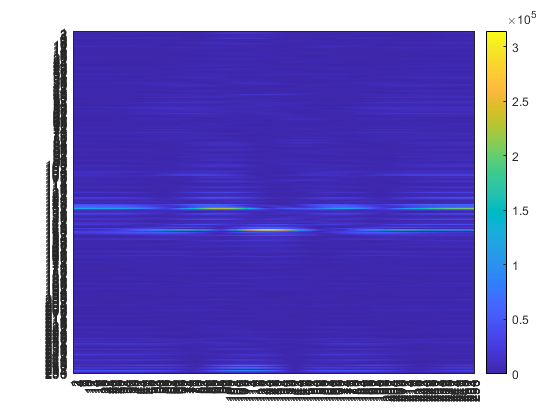

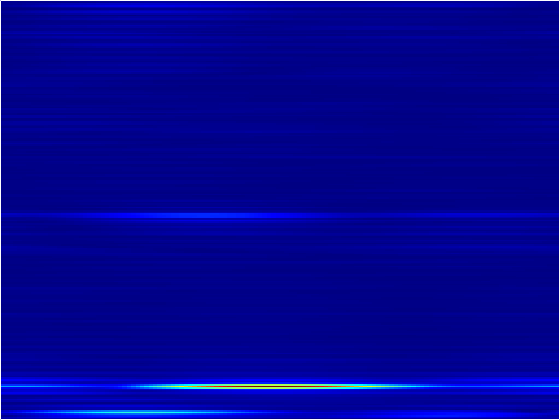

%     s = spectrogram(x,window,noverlap,nfft)



load('recdata.mat');
fs = rectdata.fs;
propspeed = rectdata.propspeed;
fc = rectdata.fc;
rxdata = rectdata.rxdata;
mfcoeffs = rectdata.mfcoeffs;
%noisepower = rectdata.noisepower;
% antennaarray = rectdata.antennaarray;
antennaarray=phased.ULA( ...
    'NumElements',4, ...
    'ElementSpacing', 0.02,"ArrayAxis", 'y',...
    'Taper', 1);


rngangresp = phased.RangeAngleResponse(...
    'SensorArray',antennaarray,'OperatingFrequency',fc,...
    'RangeMethod','FFT',... 
    'SampleRate',fs_sample,'PropagationSpeed',propspeed);

% [resp,rng_grid,ang_grid] = rngangresp(rxdata,mfcoeffs);
% 
% plotResponse(rngangresp,rxdata,mfcoeffs,'Unit','db');



    w = linspace(-1,1,128); % angle_grid
    agl_grid = asin(w)*180/pi; % [-1,1]->[-pi/2,pi/2]


    Is_Windowed=1;
%     data_each_frame = adc_sample*chirp_num*num_tx;
    data_each_frame = adc_sample*chirp_num;
    adc_tx1 = ADC_DATA(:,1:2:end);
    for i = 1:max_frame
        
        data_frame = adc_tx1(:, (i-1)*data_each_frame+1:i*data_each_frame);
        data_chirp = [];
%         for cj = 1:num_tx*chirp_num
        for cj = 1:chirp_num
            temp_A_data = data_frame(:, (cj-1)*adc_sample+1:cj*adc_sample);
            data_chirp(:,:,cj) = temp_A_data;
        end
        
        % separate the odd-index chirps and even-index chirps for TDM-MIMO with 2 TXs
%         chirp_odd = data_chirp(:,:,1:2:end);
%         chirp_even = data_chirp(:,:,2:2:end);

        
        % permutation with the format [samples, Rx, chirp]
%         chirp_odd = permute(chirp_odd, [2,1,3]);
%         chirp_even = permute(chirp_even, [2,1,3]);
        
        data_chirp = permute(data_chirp, [2,1,3]);
        
        
%         % 将排列后的数组在第二维度上进行拼接（累加）
%         combined_array = cat(2, chirp_odd, chirp_even); % 在第二维度上拼接数组
%        
%         % 查看合并后数组的大小
%         size_combined = size(combined_array); % 应该是 [256, 8, 128]
% %         
% %         % 显示结果
%         disp(['合并后数组的大小：', num2str(size_combined)]);
% %         mfcoeffs=[1;1];
        
        
        ra = squeeze(sum(data_chirp,3)/size(data_chirp,3));
% X_raw=ra;
% X_raw=data_chirp;
X_raw = detrend(ra,0); %去除直流分量
% figure(i)
% %     h = heatmap(X_slow(10:59,:));
%  h = heatmap(abs(X_raw));
%     colormap(gca, 'parula');
%     grid off;  

[resp,rng_grid,ang_grid] = rngangresp(X_raw);
% 
% resp(129,:)=[];%令0频doppler等于0 
% plotResponse(rngangresp,X_raw,'Unit','db');

figure(i+1)
%     h = heatmap(X_slow(10:59,:));
 h = heatmap(abs(resp));
    colormap(gca, 'parula');
    grid off;        
        
        data_chirp = detrend(data_chirp,0); %去除直流分量
% %         chirp_odd() = chirp_odd - mean(chirp_odd,1); % 滤除静态杂波
%         
         % Range FFT for odd chirps
        [Rangedata_odd] = fft_range(data_chirp,256,Is_Windowed);
        
        
%         % Range FFT for even chirps
%         [Rangedata_even] = fft_range(chirp_even,256,Is_Windowed);
        
%         Rangedata(:,i,j) = Rangedata(:,i,j) - repmat(mean(Rangedata(:,i,j)'),size(Rangedata(:,i,j),2),1)'; % 滤除速度为0目标
    
%         Rangedata_merge = [Rangedata_odd, Rangedata_even];
    
        
        
        % Angle FFT
        Angdata = fft_angle(Rangedata_odd,128,Is_Windowed);
%         Angdata_crop = Angdata(3+1:260-1, :, :);
        [Angdata_crop] = Normalize(Angdata, 16e+05);
        

        
        Xpow = abs(Angdata_crop);
        Xpow = squeeze(sum(Xpow,3)/size(Xpow,3));
        
%         noisefloor = db2pow(-15);
%         Xsnr=db(Xpow+eps)/2;
        Xsnr=Xpow;
%         Xsnr = pow2db(Xpow/noisefloor);
        
%         figure('visible','on')
%         % figure()
%         set(gcf,'Position',[10,10,530,420])
%         [axh] = surf(agl_grid,range_axis,Xsnr);
%         view(0,90)
%         % axis([-90 90 0 25]);
%         axis([-60 60 2 25]);
%         grid off
%         shading interp
%         xlabel('Angle of arrive(degrees)')
%         ylabel('Range(meters)')
%         colorbar
% %         caxis([0,2])
%         title('Range-Angle heatmap')
        
        
        
        
        
        figure(i);
        imagesc(Xsnr);
        colormap('jet');
% colormap(gca, 'parula');
%             caxis([80 110]);
        axis xy;
        set(gca,'xtick',[],'ytick',[],'xcolor','w','ycolor','w');
%         set(gcf,'position',[1500,400, 224, 224]);
%         set(gcf,'position',[10,10,224,224]);
        set(gca,'looseInset',[0 0 0 0]);
    
        break
    end

    
    



    
%     for tx_idx = 1 : 1
        tx_idx=1;

        [rt_plot,ud_plot] = data_stft(adc_data,adc_sample,num_tx,tx_idx,chirp_num,max_frame,overlap,min_range,max_range,range_axis);

合并后数组的大小：256  38400


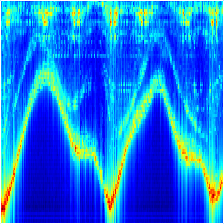

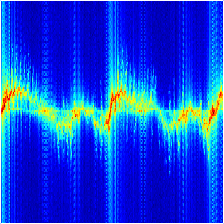

        db_rt_plot = db(rt_plot(min_range:max_range,:)+eps)/2;
        db_ud_plot = db(ud_plot+eps)/2;
        init_idx = 1;end_idx = 80;interval_idx = 80;
        
%         fra_idx=1;
         for fra_idx = 1:floor((frame_length / overlap - end_idx)/interval_idx)
            rt_data = db_rt_plot(:,init_idx+interval_idx*(fra_idx-1):end_idx+interval_idx*(fra_idx-1));
            ud_data = db_ud_plot(:,init_idx+interval_idx*(fra_idx-1):end_idx+interval_idx*(fra_idx-1));
%             ud_data = db_ud_plot;
            
            
%             cvd_plot = fftshift(fft(ud_data,size(ud_data,2),2),2);
%             cvd_data = db(cvd_plot)/2;

            figure(31);
            imagesc(db_rt_plot);
            colormap('jet');

%             caxis([80 110]);
            axis xy;
            set(gca,'xtick',[],'ytick',[],'xcolor','w','ycolor','w');
            set(gcf,'position',[1500,400, 224, 224]);
            set(gca,'looseInset',[0 0 0 0]);
%             axis off
%             f=getframe(gcf);
%             imwrite(f.cdata,['H:\RadarProcessing\Data\Origin\',act,'\rt\',strcat(files(idx).name,'_',num2str(tx_idx-1),num2str(fra_idx)),'.jpg'])            
%             saveas(1,['H:\RadarProcessing\Data\Origin\',act,'\rt\',strcat(files(idx).name,'_',num2str(tx_idx-1),num2str(fra_idx)),'.jpg']);

% 
% % 生成网格
% [x, y] = meshgrid(1:size(ud_data, 2), 1:size(ud_data, 1));
% 
% % 创建surf图像
% figure;
% surf(x, y, ud_data, 'EdgeColor', 'none');
% colormap('jet');
% caxis([80 110]);
% view(2);
% axis tight;
% set(gca,'xtick',[],'ytick',[],'xcolor','w','ycolor','w');
% set(gcf,'position',[1500,400, 224, 224]);
% set(gca,'looseInset',[0 0 0 0]);
% axis off;


            db_ud_plot(65, :) = [];
            figure(32);
            imagesc(db_ud_plot);
            colormap('jet');
%             caxis([80 110]);
            axis xy;
            set(gca,'xtick',[],'ytick',[],'xcolor','w','ycolor','w');
            set(gcf,'position',[1500,400, 224, 224]);
            set(gca,'looseInset',[0 0 0 0]);
%             axis off
%             f=getframe(gcf);
%             imwrite(f.cdata,['H:\RadarProcessing\Data\Origin\',act,'\md\',strcat(files(idx).name,'_',num2str(tx_idx-1),num2str(fra_idx)),'.jpg'])
%             saveas(2,['H:\RadarProcessing\Data\Origin\',act,'\md\',strcat(files(idx).name,'_',num2str(tx_idx-1),num2str(fra_idx)),'.jpg']);


            
%             [md_feature,cfs_feature,rt_feature] = extract_feature(velocity_axis,ud_data,rt_data,cvd_data,size(ud_data,2));
%             feature_set = [md_feature,cfs_feature,rt_feature];
%             data_name = strcat('H:\RadarProcessing\Data\Origin\',act,'\svm\',files(idx).name,'_',num2str(tx_idx-1),num2str(fra_idx),'.mat');
%             save(data_name,'feature_set');
%         end
    end

% end






function [Rangedata]=fft_range(Xcube,fft_Rang,Is_Windowed)
%%%%  Xcube : Nr*Ne*Nd , original data
%%%   fft_Rang: range fft length
%%%   fft_Vel:  velocity fft length(2D-FFT)
%%%   fft_Ang:  angle fft length(3D FFT)

Nr=size(Xcube,1);   %%%length of Chirp (number of samples)
Ne=size(Xcube,2);   %%%number of receiver
Nd=size(Xcube,3);   %%%length of chirp loop

for i=1:Ne
    for j=1:Nd
        if Is_Windowed
%             Xcube(:,i,j) = Xcube(:,i,j) - mean(Xcube(:,i,j),1); % 滤除静态杂波
            win_rng =Xcube(:,i,j).*hanning(Nr);
        else
            win_rng =Xcube(:,i,j);
        end
        Rangedata(:,i,j)=fft(win_rng,fft_Rang);
%         Rangedata(:,i,j) = Rangedata(:,i,j) - repmat(mean(Rangedata(:,i,j)'),size(Rangedata(:,i,j),2),1)'; % 滤除速度为0目标
            
    end
end
end




function [AngData] = fft_angle(Xcube,fft_Ang,Is_Windowed)

Nr=size(Xcube,1);   %%%length of Chirp
Ne=size(Xcube,2);   %%%length of receiver
Nd=size(Xcube,3);   %%%length of chirp loop

% win = taylorwin(Ne,5,-60);
% win = win/norm(win);
for i = 1:Nd
    for j = 1:Nr
        if Is_Windowed
            win_xcube = reshape(Xcube(j,:,i),Ne,1).*taylorwin(Ne);
        else
            win_xcube = reshape(Xcube(j,:,i),Ne,1).*1;
        end
        AngData(j,:,i) = fftshift(fft(win_xcube,fft_Ang));
    end
end
end



function [Angdata] = Normalize(Xcube, max_val)
% max_val = 5e+03; % unwindowed max value ###data with 1642 before July
% max_val = 3e+04; % unwindowed max value ###data with 1843 after July
Xcube = Xcube./max_val;
Angdata = single(Xcube);
end


function [rt_plot,ud_plot] = data_stft(adc_data,adc_num,tx_num,tx_idx,chirp_num,frame_num,overlap,min_range,max_range,range_axis)
    % adc_data : (1,adc_num * tx_num * chirp_num * frame_num)
    % adc_num : default-256
    % tx_num : default-3
    % chirp_num : default-128
    % overlap : default-0.5
    
    rt_plot = zeros(adc_num,frame_num / overlap);
    ud_plot = zeros(chirp_num,frame_num / overlap);
    rx_data = reshape(adc_data,adc_num,tx_num,chirp_num,frame_num);
    
    tx1_data = squeeze(rx_data(:,tx_idx,:,:));
    temp_data = reshape(tx1_data,adc_num,[]);
    
    size_combined = size(temp_data); 
%         
%         % 显示结果
    disp(['合并后数组的大小：', num2str(size_combined)]);
    
    
    temp_index = [min_range : max_range];
    for frame_idx = 1 : (frame_num -1) / overlap +1
        select_data = temp_data(:,[1:chirp_num]+chirp_num*overlap*(frame_idx-1));
        select_data = select_data - mean(select_data,1); % 滤除静态杂波
        select_data = select_data .* hanning(adc_num); % 加窗
        range_profile = fft(select_data,adc_num,1); % 距离fft 
        range_profile = range_profile - repmat(mean(range_profile'),size(range_profile,2),1)'; % 滤除速度为0目标
        
%         range_profile = detrend(range_profile,0); %去除直流分量
        
        doppler_profile = fftshift(fft(range_profile,chirp_num,2),2); % 多普勒fft
%         doppler_profile = fft(range_profile,chirp_num,2); % 多普勒fft
%         doppler_profile = doppler_profile(1:end/2,:);
        
%         doppler_profile = repmat(range_axis',1,adc_num/2).^2 * doppler_profile;

        dsum = abs(doppler_profile).^2;
        rsum = zeros(size(dsum,1),1);
        rsum(temp_index) = sum(dsum(temp_index,:),2);
        doppler_profile = (abs(doppler_profile(temp_index,:)).^2 );
        ud_plot(:,frame_idx) = sum(doppler_profile).';
        rt_plot(:,frame_idx) = rsum;   
        
         
    end
    ud_plot(:,end - 1 / overlap + 2 : end) = repmat(ud_plot(:,(frame_num - 1) / overlap + 1),1,1 / overlap - 1);
    rt_plot(:,end - 1 / overlap + 2 : end) = repmat(rt_plot(:,(frame_num - 1) / overlap + 1),1,1 / overlap - 1);
end





% %% TI官方处理代码
function [retVal] = readDCA1000(fileName)
%% global variables
% change based on sensor config
numADCSamples = 128; % number of ADC samples per chirp
numADCBits = 16; % number of ADC bits per sample
numRX = 4; % number of receivers
numLanes = 2; % do not change. number of lanes is always 2
isReal = 0; % set to 1 if real only data, 0 if complex data0
%% read file
% read .bin file
fid = fopen(fileName,'r');
adcData = fread(fid, 'int16');
% if 12 or 14 bits ADC per sample compensate for sign extension
if numADCBits ~= 16
    l_max = 2^(numADCBits-1)-1;
    adcData(adcData > l_max) = adcData(adcData > l_max) - 2^numADCBits;
end
fclose(fid);
fileSize = size(adcData, 1);
% real data reshape, filesize = numADCSamples*numChirps
if isReal
    numChirps = fileSize/numADCSamples/numRX;
    %create column for each chirp
    LVDS = reshape(adcData, numADCSamples*numRX, numChirps);
    %each row is data from one chirp
    LVDS = LVDS.';
else
    % for complex data
    % filesize = 2 * numADCSamples*numChirps
    numChirps = fileSize/2/numADCSamples/numRX;
    LVDS = zeros(1, fileSize/2);
    %combine real and imaginary part into complex data
    %read in file: 2I is followed by 2Q
    counter = 1;
    for i=1:4:fileSize-1
        LVDS(1,counter) = adcData(i) + sqrt(-1)*adcData(i+2); 
        LVDS(1,counter+1) = adcData(i+1)+sqrt(-1)*adcData(i+3); 
        counter = counter + 2;
    end
    % create column for each chirp
    LVDS = reshape(LVDS, numADCSamples*numRX, numChirps);
    %each row is data from one chirp
    LVDS = LVDS.';
end
%organize data per RX
adcData = zeros(numRX,numChirps*numADCSamples);
for row = 1:numRX
    for i = 1: numChirps
        adcData(row, (i-1)*numADCSamples+1:i*numADCSamples) = LVDS(i, (row-1)*numADCSamples+1:row*numADCSamples);
    end
end
% return receiver data
retVal = adcData;
end


